# Machovsky Experiments

clear;
avgRMSE = 0;
iter = 10;


% Define system dimensions
statenum = 3;
outputnum = 1;
inputnum = 2;
maxTime = 1000; % Total time for simulation of historical data
predTime = 20; % Part of the time that is the future

% Parameters for the algorithm
n_max = statenum; % Upper bound on the order (known from drss)
l_max = ceil(statenum / outputnum); % A simple guess for lag
delta = predTime; % Length of blocks processed in each iteration

% Create a discrete-time random state space model
sys = drss(statenum, outputnum, inputnum);

% Generate a persistently exciting input for historical data
% For example, a random signal
u_trajectory = randn(inputnum, maxTime);

% New input for prediction
newInputTime = predTime; % Length of new input
uf = randn(inputnum, newInputTime); % New input sequence

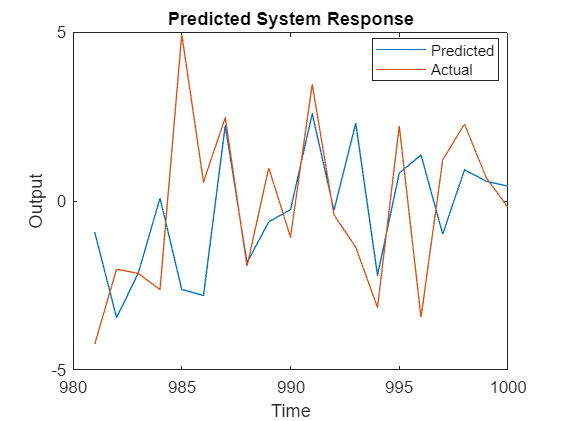

% Simulate the system to generate historical outputs
% Assuming zero initial state for simplicity
x0 = zeros(statenum, 1); % Initial state
[y_trajectory, t, x] = lsim(sys, u_trajectory', linspace(0, maxTime-1, maxTime), x0);
y_historical = y_trajectory(1:end-predTime);
y_future = y_trajectory(end-predTime+1:end);
u_historical = u_trajectory(:,1:(end-predTime));
u_future = u_trajectory(:,end-predTime+1:end);

% Predict the response using the data-driven simulation algorithm
yf = dataDrivenSimulation(u_historical, y_historical', uf, n_max, l_max, delta);

% Plot the predicted response
figure;
plot(maxTime-predTime+1:maxTime, yf);

hold on;
plot(maxTime-predTime+1:maxTime,y_future);
hold off;
legend()

title('Predicted System Response');
xlabel('Time');
ylabel('Output');

legend({'Predicted', 'Actual'}, 'Location', 'best');


avgRMSE = rmse(yf, y_future,1)

avgRMSE = 3.7049